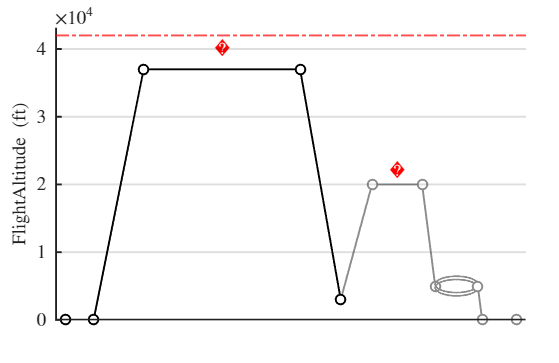

%% AIRCRAFT MISSION PROFILE (revised)
% Altitude in ft. Horizontal axis is schematic, not to scale.

clear; clc; close all;

%% 1. ADJUSTABLE PARAMETERS

% Altitudes (ft)
h_ground   = 0;
h_cruise1  = 37000;
h_ceiling  = 42000;
h_cruise2  = 20000;
h_loiter   = 5000;
h_missed   = 3000;
h_approach = 0;

% Cruise parameters
M_cruise1      = 0.82;
M_cruise2      = 0.60;
D_cruise1_nmi  = 5500;
D_cruise2_km   = 370;
loiter_minutes = 45;

% Schematic horizontal widths
w_taxi1    = 0.45;
w_climb    = 0.80;
w_cruise1  = 2.50;
w_descent1 = 0.65;
w_climb2   = 0.50;
w_cruise2  = 0.80;
w_loiter   = 1.1;
w_landing  = 0.55;

% Loiter loop horizontal radius
loiter_radius_x = 0.34;

% Plot settings
font_name   = 'Arial';
font_size   = 10;
line_width  = 1.0;
marker_size = 5;

% Display options
show_cruise_data     = true;
show_altitude_labels = false;
show_ceiling         = true;

%% 2. MISSION WAYPOINTS

widths = [w_taxi1, w_climb, w_cruise1, w_descent1, ...
          w_climb2, w_cruise2, w_loiter];

x = [0, cumsum(widths)];

% Loiter centre and entry/exit points
x_c     = x(7) + w_loiter/2;
x_entry = x_c - loiter_radius_x;
x_exit  = x_c + loiter_radius_x;

% Make descent 3 (loiter to landing) have the same gradient as
% descent 2 (cruise 2 to loiter entry)
run2 = x_entry - x(7);
run3 = run2 * (h_loiter - h_approach) / (h_cruise2 - h_loiter);
x(9)  = x_exit + run3;
x(10) = x(9) + w_landing;

% Key altitudes at each waypoint
h = [h_ground, h_ground, h_cruise1, h_cruise1, h_missed, ...
     h_cruise2, h_cruise2, h_loiter, h_approach, h_ground];

%% 3. FIGURE AND AXES

fig = figure('Color','w', 'Position',[100 100 1000 650]);

ax = axes('Parent',fig);
hold(ax,'on');
box(ax,'off');

set(ax, ...
    'FontName',font_name, ...
    'FontSize',font_size, ...
    'LineWidth',1.0, ...
    'TickLabelInterpreter','latex', ...
    'Layer','top');

ax.XTick = [];

ylabel(ax,'$\mathrm{Flight Altitude\ (ft)}$', ...
    'Interpreter','latex', ...
    'FontName',font_name, ...
    'FontSize',font_size);

ax.Position = [0.10 0.12 0.84 0.80];

xlim(ax,[x(1)-0.15, x(end)+0.15]);
ylim(ax,[-10, h_ceiling+1000]);

%% 4. COLOURS

C.nom = [0.00 0.00 0.00];   % nominal range (black)
C.div = [0.55 0.55 0.55];   % diversion range (grey)

%% 5. NOMINAL RANGE (BLACK)

% Taxi and take-off
plot(ax,x(1:2),h(1:2),'-o', ...
    'Color',C.nom,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor','k', ...
    'MarkerSize',marker_size);

% Climb to cruise 1
plot(ax,x(2:3),h(2:3),'-o', ...
    'Color',C.nom,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor','k', ...
    'MarkerSize',marker_size);

% Cruise 1
plot(ax,x(3:4),h(3:4),'-o', ...
    'Color',C.nom,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor','k', ...
    'MarkerSize',marker_size);

% Descent to missed approach point
plot(ax,x(4:5),h(4:5),'-o', ...
    'Color',C.nom,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor','k', ...
    'MarkerSize',marker_size);

%% 6. DIVERSION RANGE (GREY)

% Missed approach climb to alternate cruise
plot(ax,x(5:6),h(5:6),'-o', ...
    'Color',C.div,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor','k', ...
    'MarkerSize',marker_size);

% Alternate cruise
plot(ax,x(6:7),h(6:7),'-o', ...
    'Color',C.div,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor',C.div, ...
    'MarkerSize',marker_size);

% Descent to loiter entry
plot(ax,[x(7),x_entry],[h_cruise2,h_loiter],'-o', ...
    'Color',C.div,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor',C.div, ...
    'MarkerSize',marker_size);

% Loiter: two offset loops, as in the reference
theta = linspace(0,2*pi,300);
loiter_radius_h = loiter_radius_x * ...
    (diff(ylim(ax))/diff(xlim(ax))) / ...
    ((ax.Position(3)*fig.Position(3)) / ...
     (ax.Position(4)*fig.Position(4)));

for s = [-1 1]
    x_loop = x_c + loiter_radius_x*cos(theta);
    h_loop = h_loiter + s*0.2*loiter_radius_h + loiter_radius_h*sin(theta);
    plot(ax,x_loop,h_loop,'-', ...
        'Color',C.div,'LineWidth',line_width);
end

% Descent after loiter to approach (same gradient as descent to loiter)
plot(ax,[x_exit,x(9)],[h_loiter,h_approach],'-o', ...
    'Color',C.div,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor',C.div, ...
    'MarkerSize',marker_size);

% Landing and taxi
plot(ax,x(9:10),h(9:10),'-o', ...
    'Color',C.div,'LineWidth',line_width, ...
    'MarkerFaceColor','w','MarkerEdgeColor',C.div, ...
    'MarkerSize',marker_size);

%% 7. ALTITUDE REFERENCE LINE (OPTIONAL)

if show_ceiling
    yline(ax,h_ceiling,'-.', ...
        'Color','r', ...
        'LineWidth',1.0, ...
        'HandleVisibility','off');
end

%% 8. TEXT LABELS

% Helper: wrap plain text as LaTeX roman text
txt = @(s) ['$\mathrm{' strrep(s,' ','\ ') '}$'];

if show_altitude_labels
    text(ax,mean(x(3:4)),h_cruise1+1000, ...
        txt(sprintf('Cruise 1: %.0f ft',h_cruise1)), ...
        'Interpreter','latex', ...
        'FontName',font_name,'FontSize',font_size, ...
        'HorizontalAlignment','center');

    text(ax,mean(x(6:7)),h_cruise2+1000, ...
        txt(sprintf('Cruise 2: %.0f ft',h_cruise2)), ...
        'Interpreter','latex', ...
        'FontName',font_name,'FontSize',font_size, ...
        'HorizontalAlignment','center');

    text(ax,x_c,h_loiter+loiter_radius_h+1000, ...
        txt(sprintf('%.0f min @ %.0f ft',loiter_minutes,h_loiter)), ...
        'Interpreter','latex', ...
        'FontName',font_name,'FontSize',font_size, ...
        'HorizontalAlignment','center');
end

if show_cruise_data
    text(ax,mean(x(3:4)),h_cruise1+3500, ...
        txt(sprintf('%.0f nmi @ Mach %.2f',D_cruise1_nmi,M_cruise1)), ...
        'Interpreter','latex', ...
        'FontName',font_name,'FontSize',font_size, ...
        'HorizontalAlignment','center');

    text(ax,mean(x(6:7)),h_cruise2+2500, ...
        txt(sprintf('%.0f km @ Mach %.2f',D_cruise2_km,M_cruise2)), ...
        'Interpreter','latex', ...
        'FontName',font_name,'FontSize',font_size, ...
        'HorizontalAlignment','center');
end

%% 9. FINAL FORMATTING

% No legend
legend(ax,'off');

% Enforce Arial 10 on all text objects
set(findall(fig,'-property','FontName'), 'FontName', font_name);
set(findall(fig,'-property','FontSize'), 'FontSize', font_size);
grid on;
hold(ax,'off');


%% 10. PRINT MISSION PARAMETERS

fprintf('\n===== AIRCRAFT MISSION PARAMETERS =====\n');


===== AIRCRAFT MISSION PARAMETERS =====


fprintf('Ceiling: %.0f ft\n', h_ceiling);

Ceiling: 42000 ft


fprintf('Cruise 1: %.0f ft, Mach %.2f, %.0f nmi\n', ...
    h_cruise1, M_cruise1, D_cruise1_nmi);

Cruise 1: 37000 ft, Mach 0.82, 5500 nmi


fprintf('Cruise 2: %.0f ft, Mach %.2f, %.0f km\n', ...
    h_cruise2, M_cruise2, D_cruise2_km);

Cruise 2: 20000 ft, Mach 0.60, 370 km


fprintf('Loiter: %.0f ft for %.0f minutes\n', ...
    h_loiter, loiter_minutes);

Loiter: 5000 ft for 45 minutes


fprintf('Descent gradient (both): %.0f ft per unit width\n', ...
    (h_cruise2 - h_loiter) / run2);

Descent gradient (both): 71429 ft per unit width


fprintf('=======================================\n');